%% COVID-19 FINAL ANALYSIS: STANDARDIZED DLM (7 TO 21 DAYS LAG)
%  Focusing solely on Model 3 (Fixed Effects, No Harmonic Seasonality)
%  Variables: UV vs. Temperature vs. Sunlight
%  ALL Environmental Variables are Z-Score Normalized.
%  Lags: 7 to 21 days.

clear; clc; close all;
fprintf('>>> STARTING ANALYSIS: STANDARDIZED DLM (7-21 DAYS LAG) <<<\n');

>>> STARTING ANALYSIS: STANDARDIZED DLM (7-21 DAYS LAG) <<<



%% 1. LOAD SOCIO-ECONOMIC DATA
fprintf('1. Loading Socio-Economic Factors...\n');

1. Loading Socio-Economic Factors...


files = {'diabetes.xlsx', 'Obesity_List.xlsx', 'AgerOver65 copy.xlsx', ...
         'Respiratory.xlsx', 'lifeexpectancy.xlsx', 'unemployment.xlsx'};
cols  = {'Prevalence of diabetes', 'Obezite_Orani', 'Yas_65_Ustu_Orani', ...
         'Respiratory Diseases', 'life expectancy', 'unemployment'};
N_full = 129; 
raw_static = zeros(N_full, 6); 

for i = 1:6
    try
        opts = detectImportOptions(files{i}); opts.VariableNamingRule = 'preserve';
        if ismember(files{i}, {'Respiratory.xlsx','lifeexpectancy.xlsx','unemployment.xlsx'}), opts.Sheet = 'Sheet1'; end
        tbl = readtable(files{i}, opts);
        raw_col = tbl.(cols{i});
        if iscell(raw_col) || isstring(raw_col), v = str2double(replace(string(raw_col), [",", """"], [".", ""]));
        else, v = raw_col; end
        v(isnan(v)) = mean(v, 'omitnan'); 
        len = min(length(v), N_full); raw_static(1:len, i) = v(1:len);
    catch
        raw_static(:, i) = 0; 
    end
end

%% 2. TIME SERIES, CLIMATE & CONFOUNDER DATA
fprintf('2. Processing Time Series & Climate Data...\n');

2. Processing Time Series & Climate Data...


startDate = datetime(2020,1,21); endDate = datetime(2023,1,10);  

T_temp = readtable('degrees.xlsx'); temps = T_temp{:, 22:end-5}; 

T_uv = readtable('UV.xlsx'); uvIndex = T_uv{:, 22:end-5};

T_sun = readtable('sunshine.xlsx'); sunshine = T_sun{:, 22:end-5};


T_hum = readtable('humidity.xlsx'); humIndex = T_hum{:, 22:end-5};

T_pm25 = readtable('PM25.xlsx'); pm25Index = T_pm25{:, 22:end-5};


data_us = readtable('us-states.csv');
if ~isdatetime(data_us.date), data_us.date = datetime(data_us.date, 'InputFormat', 'yyyy-MM-dd'); end
data_us = data_us(data_us.date >= startDate & data_us.date <= endDate, :);
all_dates = unique(data_us.date); states = unique(data_us.state); n_us = length(states);

deaths_us = zeros(n_us, length(all_dates));
for i = 1:height(data_us)
    s = find(strcmp(states, data_us.state{i})); d = find(all_dates == data_us.date(i));
    deaths_us(s, d) = data_us.deaths(i);
end
daily_us = zeros(n_us, length(all_dates)); 
for i = 1:n_us, d = [0, diff(deaths_us(i, :))]; d(d < 0) = 0; daily_us(i, :) = movmean(d, 7); end

owid = readtable("owid-covid-data.csv");
if ~isdatetime(owid.date), owid.date = datetime(owid.date, 'InputFormat', 'yyyy-MM-dd'); end
owid = owid(owid.date >= startDate & owid.date <= endDate, :);
countries_small = ["Luxembourg", "Malta", "Cyprus", "Estonia", "Latvia", "Lithuania", "Slovenia", "Slovakia", "Czechia", "Belgium", "Netherlands", "Switzerland", "Denmark", "Ireland", "Iceland", "Singapore", "Bahrain", "Qatar", "Kuwait", "United Arab Emirates", "Trinidad and Tobago", "Jamaica", "Seychelles", "Maldives", "Mauritius", "Cape Verde", "Gibraltar", "Isle of Man", "Macao", "Hong Kong", "New Caledonia", "French Polynesia", "Marshall Islands", "Micronesia (country)", "Solomon Islands", "Timor", "Tonga", "Taiwan", "Samoa", "San Marino", "Saint Lucia", "Saint Kitts and Nevis", "Saint Vincent and the Grenadines", "Palestine", "Monaco", "Liechtenstein", "Kosovo", "Kiribati", "Grenada", "Fiji", "Dominica", "Curacao", "Brunei", "British Virgin Islands", "Belize", "Bahamas", "Aruba", "Andorra", "Antigua and Barbuda", "Norway", "Sweden", "Finland", "Israel", "Uruguay", "Albania", "Serbia", "Bosnia and Herzegovina", "Hungary", "Austria", "Croatia", "North Macedonia", "El Salvador", "Haiti"];

deaths_intl = zeros(length(countries_small), length(all_dates));
for i = 1:length(countries_small)
    kk = owid(strcmp(string(owid.location), countries_small(i)), :);
    [~, idx_d, idx_t] = intersect(kk.date, all_dates);
    if ~isempty(idx_d), d_val = kk.new_deaths(idx_d); if iscell(d_val), d_val = str2double(d_val); end; d_val(isnan(d_val)) = 0; deaths_intl(i, idx_t) = movmean(d_val, 7)'; end
end
daily_full = [daily_us; deaths_intl];

% Dimensions Check
min_N = min([size(daily_full,1), size(temps,1), size(humIndex,1), size(pm25Index,1), N_full]);
Y_mat = daily_full(1:min_N, :); T_mat = temps(1:min_N, :); U_mat = uvIndex(1:min_N, :); S_mat = sunshine(1:min_N, :);
H_mat = humIndex(1:min_N, :); P_mat = pm25Index(1:min_N, :);

min_T = min([size(Y_mat,2), size(T_mat,2), size(H_mat,2), size(P_mat,2)]);
Y_mat = Y_mat(:, 1:min_T); T_mat = T_mat(:, 1:min_T); U_mat = U_mat(:, 1:min_T); S_mat = S_mat(:, 1:min_T);
H_mat = H_mat(:, 1:min_T); P_mat = P_mat(:, 1:min_T);

pop_table = readtable('population.xlsx'); Pop_Vector = pop_table.Population(1:min_N);

%% 3. NORMALIZATION (Z-SCORE)
fprintf('3. Normalizing all environmental variables...\n');

3. Normalizing all environmental variables...


U_mat = (U_mat - mean(U_mat(:), 'omitnan')) ./ std(U_mat(:), 'omitnan');
T_mat = (T_mat - mean(T_mat(:), 'omitnan')) ./ std(T_mat(:), 'omitnan');
S_mat = (S_mat - mean(S_mat(:), 'omitnan')) ./ std(S_mat(:), 'omitnan');
H_mat = (H_mat - mean(H_mat(:), 'omitnan')) ./ std(H_mat(:), 'omitnan');
P_mat = (P_mat - mean(P_mat(:), 'omitnan')) ./ std(P_mat(:), 'omitnan');

%% 4. PREPARE LAGS (EXTENDED: 7 TO 21 DAYS)
fprintf('4. Preparing Lags (7 to 21) and Master Table...\n');

4. Preparing Lags (7 to 21) and Master Table...


All_Names = [cellstr(states); cellstr(countries_small')];

max_lag = 21; min_lag = 7; 
Y_final = Y_mat(:, 1+max_lag:end); 
n_T = size(Y_final, 2); n_R = size(Y_final, 1);
Y_vec = reshape(Y_final', [], 1);
Pop_v = repelem(Pop_Vector, n_T, 1);
Time_v = repmat((1:n_T)', n_R, 1); 
Region_ID = categorical(repelem((1:n_R)', n_T, 1));

T_Lags = []; U_Lags = []; S_Lags = []; H_Lags = []; P_Lags = []; 
T_Names = {}; U_Names = {}; S_Names = {}; Hum_Names = {}; PM25_Names = {};

for k = min_lag:max_lag
    T_k = T_mat(:, (1+max_lag-k) : (end-k)); U_k = U_mat(:, (1+max_lag-k) : (end-k)); S_k = S_mat(:, (1+max_lag-k) : (end-k));
    H_k = H_mat(:, (1+max_lag-k) : (end-k)); P_k = P_mat(:, (1+max_lag-k) : (end-k));
    
    T_Lags = [T_Lags, reshape(T_k', [], 1)]; U_Lags = [U_Lags, reshape(U_k', [], 1)]; S_Lags = [S_Lags, reshape(S_k', [], 1)];
    H_Lags = [H_Lags, reshape(H_k', [], 1)]; P_Lags = [P_Lags, reshape(P_k', [], 1)];
    
    T_Names{end+1} = sprintf('TempLag%d', k);
    U_Names{end+1} = sprintf('UVLag%d', k);
    S_Names{end+1} = sprintf('SunLag%d', k);
    Hum_Names{end+1} = sprintf('HumLag%d', k);     
    PM25_Names{end+1} = sprintf('PMLag%d', k);     
end

% THE MASTER TABLE
T_Base = table(Y_vec, Pop_v, Time_v, Region_ID, ...
    'VariableNames', {'Death','Pop','Time','Region'});
log_off = log(T_Base.Pop);

T_Base = [T_Base, array2table(U_Lags, 'VariableNames', U_Names)];
T_Base = [T_Base, array2table(T_Lags, 'VariableNames', T_Names)];
T_Base = [T_Base, array2table(S_Lags, 'VariableNames', S_Names)];
T_Base = [T_Base, array2table(H_Lags, 'VariableNames', Hum_Names)];
T_Base = [T_Base, array2table(P_Lags, 'VariableNames', PM25_Names)];

idx_valid = (T_Base.Pop > 0) & ~any(isnan(T_Lags), 2) & ~any(isnan(U_Lags), 2) & ~any(isnan(H_Lags), 2) & ~any(isnan(P_Lags), 2) & ~isnan(Y_vec);
T_Base = T_Base(idx_valid, :); log_off = log_off(idx_valid);

%% 5. RUN EXPLICIT DLM MODELS (UV, TEMP, SUN)
fprintf('5. Running DLM Models (Normalized Variables, 7-21 Lags)...\n');

5. Running DLM Models (Normalized Variables, 7-21 Lags)...



conf_str = 'HumLag7 + HumLag8 + HumLag9 + HumLag10 + HumLag11 + HumLag12 + HumLag13 + HumLag14 + HumLag15 + HumLag16 + HumLag17 + HumLag18 + HumLag19 + HumLag20 + HumLag21 + PMLag7 + PMLag8 + PMLag9 + PMLag10 + PMLag11 + PMLag12 + PMLag13 + PMLag14 + PMLag15 + PMLag16 + PMLag17 + PMLag18 + PMLag19 + PMLag20 + PMLag21';

form_M3_UV   = ['Death ~ Time + Region + ', conf_str, ' + UVLag7 + UVLag8 + UVLag9 + UVLag10 + UVLag11 + UVLag12 + UVLag13 + UVLag14 + UVLag15 + UVLag16 + UVLag17 + UVLag18 + UVLag19 + UVLag20 + UVLag21'];
form_M3_Temp = ['Death ~ Time + Region + ', conf_str, ' + TempLag7 + TempLag8 + TempLag9 + TempLag10 + TempLag11 + TempLag12 + TempLag13 + TempLag14 + TempLag15 + TempLag16 + TempLag17 + TempLag18 + TempLag19 + TempLag20 + TempLag21'];
form_M3_Sun  = ['Death ~ Time + Region + ', conf_str, ' + SunLag7 + SunLag8 + SunLag9 + SunLag10 + SunLag11 + SunLag12 + SunLag13 + SunLag14 + SunLag15 + SunLag16 + SunLag17 + SunLag18 + SunLag19 + SunLag20 + SunLag21'];

fprintf('   - Fitting Normalized UV Model...\n');

   - Fitting Normalized UV Model...


M3_UV_mdl   = fitglm(T_Base, form_M3_UV, 'Distribution', 'poisson', 'Offset', log_off);
[M3_UV_tbl, M3_UV_disp, M3_UV_r2] = calculate_robust_table(M3_UV_mdl, log_off);

fprintf('   - Fitting Normalized Temp Model...\n');

   - Fitting Normalized Temp Model...


M3_Temp_mdl = fitglm(T_Base, form_M3_Temp, 'Distribution', 'poisson', 'Offset', log_off);
[M3_Temp_tbl, M3_Temp_disp, M3_Temp_r2] = calculate_robust_table(M3_Temp_mdl, log_off);

fprintf('   - Fitting Normalized Sun Model...\n');

   - Fitting Normalized Sun Model...


M3_Sun_mdl  = fitglm(T_Base, form_M3_Sun, 'Distribution', 'poisson', 'Offset', log_off);
[M3_Sun_tbl, M3_Sun_disp, M3_Sun_r2] = calculate_robust_table(M3_Sun_mdl, log_off);

%% 6. VISUALIZATIONS
fprintf('6. Generating Visualizations...\n');

6. Generating Visualizations...


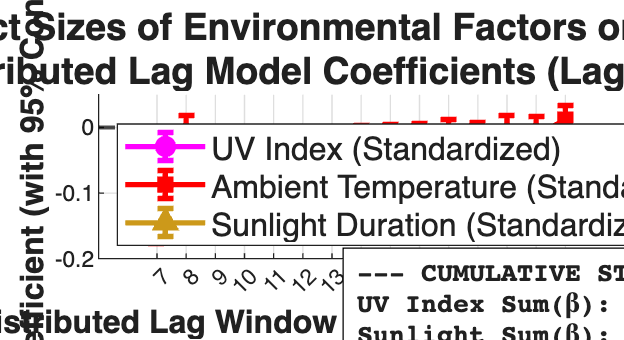


% Extract Arrays for Plotting
uv_est = M3_UV_tbl.Estimate(ismember(M3_UV_tbl.Predictor, U_Names));
uv_se  = M3_UV_tbl.RobustSE(ismember(M3_UV_tbl.Predictor, U_Names));
uv_sum_beta = sum(uv_est); 

temp_est = M3_Temp_tbl.Estimate(ismember(M3_Temp_tbl.Predictor, T_Names));
temp_se  = M3_Temp_tbl.RobustSE(ismember(M3_Temp_tbl.Predictor, T_Names));
temp_sum_beta = sum(temp_est); 

sun_est = M3_Sun_tbl.Estimate(ismember(M3_Sun_tbl.Predictor, S_Names));
sun_se  = M3_Sun_tbl.RobustSE(ismember(M3_Sun_tbl.Predictor, S_Names));
sun_sum_beta = sum(sun_est); 

% --- PLOT 1: FOREST PLOT FOR SIGNIFICANCE COMPARISON ---
figure('Name', 'Figure 1: Standardized Effect Sizes', 'Color', 'w', 'Position', [50 50 1100 600]);
hold on;
errorbar(min_lag:max_lag, uv_est, 1.96*uv_se, 'm-o', 'LineWidth', 2, 'MarkerFaceColor', 'm', 'DisplayName', 'UV Index (Standardized)');
errorbar(min_lag:max_lag, temp_est, 1.96*temp_se, 'r-s', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'DisplayName', 'Ambient Temperature (Standardized)');
errorbar(min_lag:max_lag, sun_est, 1.96*sun_se, 'color', [0.8 0.6 0.1], 'Marker', '^', 'LineStyle', '-', 'LineWidth', 2, 'MarkerFaceColor', [0.8 0.6 0.1], 'DisplayName', 'Sunlight Duration (Standardized)');

yline(0, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
grid on; legend('Location', 'southwest', 'FontSize', 12);
xlabel('Distributed Lag Window (Days before Mortality)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Standardized Coefficient (with 95% Confidence Interval)', 'FontSize', 12, 'FontWeight', 'bold');
title({'Standardized Effect Sizes of Environmental Factors on COVID-19 Mortality', ...
       'Distributed Lag Model Coefficients (Lags 7-21)'}, 'FontSize', 14);
xticks(7:21); 

text_str = {
    '--- CUMULATIVE STANDARDIZED EFFECTS (Lags 7-21) ---',
    sprintf('UV Index Sum(\x03B2):      %.4f', uv_sum_beta),
    sprintf('Sunlight Sum(\x03B2):      %.4f', sun_sum_beta),
    sprintf('Temperature Sum(\x03B2):   %.4f', temp_sum_beta)
};
annotation('textbox', [0.55 0.15 0.35 0.12], 'String', text_str, ...
    'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', ...
    'FontSize', 10, 'FontName', 'Courier', 'FontWeight', 'bold');
hold off;

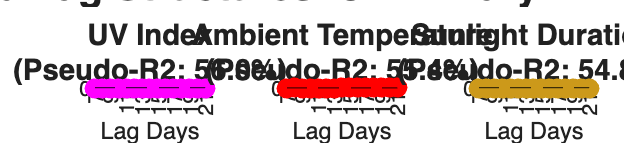


% --- PLOT 2: LAG STRUCTURE COMPARISON ---
figure('Name', 'Figure 2: Isolated Lag Structures', 'Color', 'w', 'Position', [100 100 1500 400]);
tl2 = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
errorbar(min_lag:max_lag, uv_est, 1.96*uv_se, 'm-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'm');
yline(0, 'k--'); grid on; xticks(7:2:21);
title(sprintf('UV Index\n(Pseudo-R2: %.1f%%)', M3_UV_r2*100), 'FontSize', 11);
xlabel('Lag Days'); ylabel('Log Relative Risk');

nexttile;
errorbar(min_lag:max_lag, temp_est, 1.96*temp_se, 'r-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
yline(0, 'k--'); grid on; xticks(7:2:21);
title(sprintf('Ambient Temperature\n(Pseudo-R2: %.1f%%)', M3_Temp_r2*100), 'FontSize', 11);
xlabel('Lag Days');

nexttile;
errorbar(min_lag:max_lag, sun_est, 1.96*sun_se, '-o', 'Color', [0.8 0.6 0.1], 'LineWidth', 1.5, 'MarkerFaceColor', [0.8 0.6 0.1]);
yline(0, 'k--'); grid on; xticks(7:2:21);
title(sprintf('Sunlight Duration\n(Pseudo-R2: %.1f%%)', M3_Sun_r2*100), 'FontSize', 11);
xlabel('Lag Days');
title(tl2, 'Isolated Distributed Lag Structures for Primary Environmental Predictors', 'FontSize', 15, 'FontWeight', 'bold');

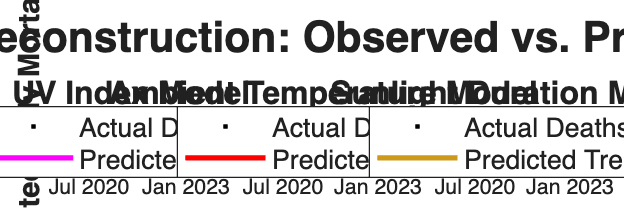


% --- PLOT 3: GLOBAL FIT COMPARISON ---
dates_uniq = unique(T_Base.Time);
real_dates = startDate + caldays(dates_uniq + max_lag); 
g_act = zeros(length(dates_uniq), 1);
for i = 1:length(dates_uniq)
    g_act(i) = mean(T_Base.Death(T_Base.Time == dates_uniq(i)), 'omitnan');
end

figure('Name', 'Figure 3: Global Time-Series Reconstruction', 'Color', 'w', 'Position', [150 150 1500 500]);
tl3 = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

mdls = {M3_UV_mdl, M3_Temp_mdl, M3_Sun_mdl};
colors = {'m', 'r', [0.8 0.6 0.1]};
titles = {'UV Index Model', 'Ambient Temperature Model', 'Sunlight Duration Model'};

for v = 1:3
    nexttile;
    y_pred = predict(mdls{v});
    g_pred = zeros(length(dates_uniq), 1);
    for i = 1:length(dates_uniq)
        g_pred(i) = mean(y_pred(T_Base.Time == dates_uniq(i)), 'omitnan');
    end
    h1 = plot(real_dates, g_act, 'k.', 'MarkerSize', 5); hold on;
    h2 = plot(real_dates, g_pred, '-', 'Color', colors{v}, 'LineWidth', 2);
    
    legend([h1, h2], {'Actual Deaths', 'Predicted Trend'}, 'Location', 'best', 'FontSize', 10);
    title(titles{v}, 'FontSize', 12, 'FontWeight', 'bold');
    grid on; axis tight;
    if v == 1, ylabel('Aggregated Daily Mortality', 'FontSize', 11, 'FontWeight', 'bold'); end
end
title(tl3, 'Global Time-Series Reconstruction: Observed vs. Predicted Daily Mortality', 'FontSize', 16, 'FontWeight', 'bold');


% --- PLOT 4: REGIONAL PREDICTIVE ACCURACY (GÖSTERGE HATASI ÇÖZÜLDÜ) ---
fprintf('7. Generating Regional Fit Plots...\n');

7. Generating Regional Fit Plots...


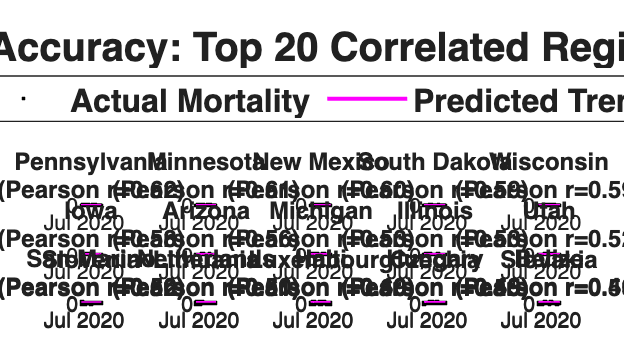

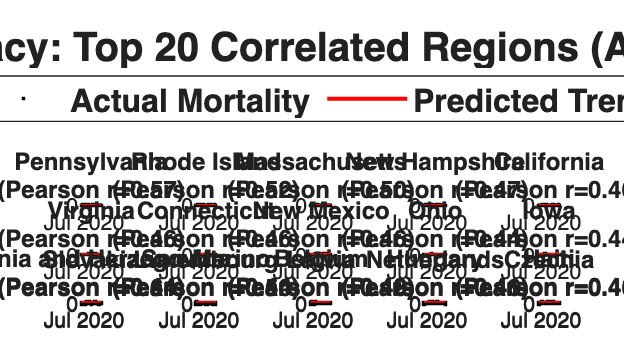

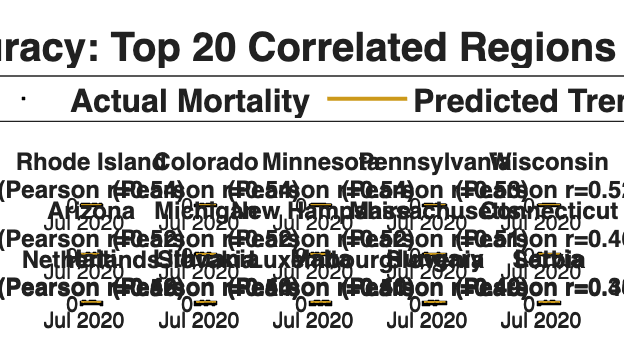

regions_cat = unique(T_Base.Region);
mdl_array = {M3_UV_mdl, M3_Temp_mdl, M3_Sun_mdl};
mdl_names = {'UV Index', 'Ambient Temperature', 'Sunlight Duration'};
mdl_colors = {'m', 'r', [0.8 0.6 0.1]};

for m = 1:3
    y_pred_current = predict(mdl_array{m});
    region_scores = zeros(length(regions_cat), 1);
    
    for i = 1:length(regions_cat)
        idx = (T_Base.Region == regions_cat(i));
        if sum(idx) > 50 
            region_scores(i) = corr(T_Base.Death(idx), y_pred_current(idx), 'Rows', 'complete', 'Type', 'Pearson');
        else
            region_scores(i) = -1;
        end
    end

    us_mask = (double(regions_cat) <= n_us); 
    [~, us_sort] = sort(region_scores(us_mask), 'descend');
    top_us = regions_cat(us_mask); top_us_idx = us_sort(1:10);
    best_us_scores = region_scores(us_mask); best_us_scores = best_us_scores(top_us_idx);
    top_us = top_us(top_us_idx);

    world_mask = (double(regions_cat) > n_us);
    [~, w_sort] = sort(region_scores(world_mask), 'descend');
    top_world = regions_cat(world_mask); top_world_idx = w_sort(1:10);
    best_world_scores = region_scores(world_mask); best_world_scores = best_world_scores(top_world_idx);
    top_world = top_world(top_world_idx);

    Final_Regions = [top_us; top_world]; Final_Scores = [best_us_scores; best_world_scores]; 
    Final_Names = All_Names(double(Final_Regions));

    figure('Name', sprintf('Figure 4: Regional Fit - %s', mdl_names{m}), 'Color', 'w', 'Position', [100+(m*30) 100+(m*30) 1600 900]);
    tl4 = tiledlayout(4, 5, 'TileSpacing', 'compact', 'Padding', 'normal');
    
    for i = 1:20
        nexttile;
        r_id = Final_Regions(i); idx = (T_Base.Region == r_id);
        
        T_loc = table(T_Base.Time(idx), T_Base.Death(idx), y_pred_current(idx), 'VariableNames', {'Time', 'Act', 'Pred'});
        T_loc = sortrows(T_loc, 'Time');
        [~, loc] = ismember(T_loc.Time, dates_uniq);
        p_dates = real_dates(loc);
        
        h1 = plot(p_dates, T_loc.Act, 'k.', 'MarkerSize', 4); hold on;
        h2 = plot(p_dates, T_loc.Pred, '-', 'Color', mdl_colors{m}, 'LineWidth', 1.5);
        
        title(sprintf('%s\n(Pearson r=%.2f)', Final_Names{i}, Final_Scores(i)), 'Interpreter', 'none', 'FontSize', 9, 'FontWeight', 'bold');
        grid on; axis tight;
    end
    
    title(tl4, sprintf('Regional Predictive Accuracy: Top 20 Correlated Regions (%s Model)', mdl_names{m}), 'FontSize', 15, 'FontWeight', 'bold');
    
    % MÜKEMMEL ÇÖZÜM: Tüm sayfanın tepesine yerleşen tek ve devasa bir gösterge (Legend)
    lgd = legend([h1, h2], {'Actual Mortality', 'Predicted Trend'}, 'Orientation', 'horizontal', 'FontSize', 12, 'FontWeight', 'bold');
    lgd.Layout.Tile = 'north'; % Bu komut legend'ı otomatik olarak merkeze ve tepeye yaslar.
end


% --- PLOT 5: RAW ENVIRONMENTAL DATA OVERVIEW FOR TOP 20 REGIONS ---
fprintf('8. Generating Environmental Data Overview (Figure 5)...\n');

8. Generating Environmental Data Overview (Figure 5)...


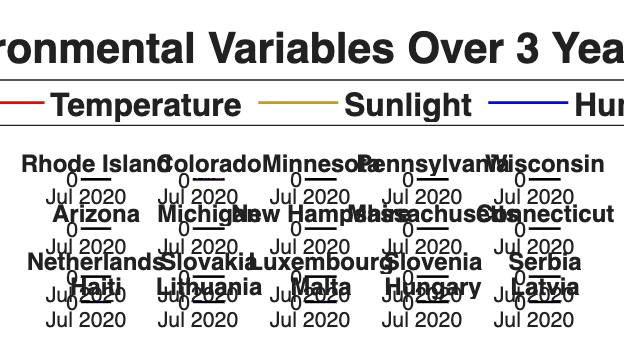

figure('Name', 'Figure 5: Environmental Data Overview', 'Color', 'w', 'Position', [200 200 1600 900]);
tl5 = tiledlayout(4, 5, 'TileSpacing', 'compact', 'Padding', 'normal');

% 3 yıllık tam tarihi oluştur
data_dates = startDate + caldays(0:(min_T-1));

for i = 1:20
    nexttile;
    r_id = Final_Regions(i); % UV Modelinde en iyi uyan aynı 20 bölge
    
    p_uv = plot(data_dates, U_mat(r_id, :), 'm', 'LineWidth', 1); hold on;
    p_temp = plot(data_dates, T_mat(r_id, :), 'r', 'LineWidth', 1);
    p_sun = plot(data_dates, S_mat(r_id, :), 'Color', [0.8 0.6 0.1], 'LineWidth', 1);
    p_hum = plot(data_dates, H_mat(r_id, :), 'b', 'LineWidth', 1);
    p_pm = plot(data_dates, P_mat(r_id, :), 'k', 'LineWidth', 1);
    
    title(Final_Names{i}, 'Interpreter', 'none', 'FontSize', 9, 'FontWeight', 'bold');
    grid on; axis tight;
end

title(tl5, 'Standardized Environmental Variables Over 3 Years (Top 20 Regions)', 'FontSize', 16, 'FontWeight', 'bold');
lgd5 = legend([p_uv, p_temp, p_sun, p_hum, p_pm], ...
    {'UV Index', 'Temperature', 'Sunlight', 'Humidity', 'PM 2.5'}, ...
    'Orientation', 'horizontal', 'FontSize', 12, 'FontWeight', 'bold');
lgd5.Layout.Tile = 'north'; % Ekrana sığacak şekilde en tepeye yerleşir


%% 7. EXCEL EXPORT
fprintf('9. Exporting Results to Excel...\n');

9. Exporting Results to Excel...


filename = 'Model_Standardized_7to21Lags.xlsx'; 

if exist(filename, 'file')
    delete(filename);
end

Metrics_List = {'UV Index Model'; 'Ambient Temp Model'; 'Sunlight Model'};
Disp_List = [M3_UV_disp; M3_Temp_disp; M3_Sun_disp];
R2_List   = [M3_UV_r2; M3_Temp_r2; M3_Sun_r2] * 100;
Sum_Beta_List = [uv_sum_beta; temp_sum_beta; sun_sum_beta];

Summary_Table = table(Metrics_List, Disp_List, R2_List, Sum_Beta_List, ...
    'VariableNames', {'Environmental_Model', 'Dispersion_Parameter', 'Pseudo_R2_Percent', 'Sum_of_Standardized_Betas'});

try
    writetable(Summary_Table, filename, 'Sheet', '1_Summary_Metrics', 'WriteRowNames', false);
    writetable(M3_UV_tbl, filename, 'Sheet', '2_UV_Coefs', 'WriteRowNames', false);
    writetable(M3_Temp_tbl, filename, 'Sheet', '3_Temp_Coefs', 'WriteRowNames', false);
    writetable(M3_Sun_tbl, filename, 'Sheet', '4_Sun_Coefs', 'WriteRowNames', false);
    fprintf('✅ Excel Export Saved: %s\n', filename);
catch ME
    warning('Hata: %s', ME.message);
end

✅ Excel Export Saved: Model_Standardized_7to21Lags.xlsx


fprintf('✅ Standadized DLM Analysis (7-21 Lags) Complete!\n');

✅ Standadized DLM Analysis (7-21 Lags) Complete!



%% LOCAL FUNCTION 
function [ResultTable, Dispersion, PseudoR2] = calculate_robust_table(mdl, log_off)
    Dispersion = sqrt(mdl.Deviance / mdl.DFE);
    beta = mdl.Coefficients.Estimate;
    se_robust = mdl.Coefficients.SE * Dispersion;
    t_stat = beta ./ se_robust;
    p_val = 2 * (1 - tcdf(abs(t_stat), mdl.DFE));
    
    mdl_null = fitglm(mdl.Variables, 'Death ~ 1', 'Distribution', 'poisson', 'Offset', log_off);
    PseudoR2 = 1 - (mdl.Deviance / mdl_null.Deviance);
    
    Predictor = mdl.CoefficientNames';
    ResultTable = table(Predictor, beta, se_robust, t_stat, p_val, ...
        'VariableNames', {'Predictor', 'Estimate', 'RobustSE', 'tStat', 'pValue'});
end